# $k_{\mathrm{app}}^{\mathrm{Vmax}}$ estimation

clear

$k_{\mathrm{app}}^{\mathrm{Vmax}}$=$\frac{V_{\mathrm{max}} \left(C\right)}{E\left(C\right)}$

abundance_data

activity_data

kcat_data_plant

## Sulpice et al. data set

kapp_Vmax_Seaton = (vmax_Seaton./abundance_per_EC_mg_gFW_Seaton)/60;
kapp_Vmax_Seaton_std = (vmax_Seaton_std./abundance_per_EC_mg_gFW_Seaton)/60;

## Piques et al. data set

kapp_Vmax_Piques = (vmax_Piques./abundance_per_EC_mg_gFW_Piques)/60;
kapp_Vmax_Piques_std = (vmax_Piques_std./abundance_per_EC_mg_gFW_Piques)/60;

## Pyl et al. data set

kapp_Vmax_Pyl = (vmax_Pyl./abundance_per_EC_mg_gFW_Pyl)/60;
kapp_Vmax_Pyl_std = (vmax_Pyl_std./abundance_per_EC_mg_gFW_Pyl)/60;

% Combine data set to one (Piques Pyl Seaton data)
vmax_combined_all = [vmax_Pyl vmax_Piques vmax_Seaton];
kapp_Vmax_combined_all = [kapp_Vmax_Pyl kapp_Vmax_Piques kapp_Vmax_Seaton];
kapp_Vmax_std_combined_all = [kapp_Vmax_Pyl_std kapp_Vmax_Piques_std kapp_Vmax_Seaton_std];
abundance_per_EC_mg_gFW_combined_all = [abundance_per_EC_mg_gFW_Pyl abundance_per_EC_mg_gFW_Piques abundance_per_EC_mg_gFW_Seaton];
abundance_per_EC_mg_gDW_combined_all = [abundance_per_EC_mg_gDW_Pyl abundance_per_EC_mg_gDW_Piques abundance_per_EC_mg_gDW_Seaton];

% maximum kapp_Vmax over all conditions
[kapp_Vmax_combined_all_max,idx_max] = max(kapp_Vmax_combined_all,[],2,"omitnan");
for i=1:size(kapp_Vmax_std_combined_all,1)
    kapp_Vmax_std_combined_all_max(i,1) = kapp_Vmax_std_combined_all(i,idx_max(i));
end


# RESULT 1

# VARIANCE $k_{\mathrm{app}}^{\mathrm{Vmax}}$

C=triu(corr(kapp_Vmax_combined_all,'rows','pairwise'),1);

disp('Minimum correlation kapp_Vmax across conditions:')

Minimum correlation kapp_Vmax across conditions:


min(C(C>0),[],'all')

ans = 0.3095


disp('Average correlation kapp_Vmax across conditions:')

Average correlation kapp_Vmax across conditions:


mean(C(C>0),'all')

ans = 0.9182


save('Result1.mat')

## Supplementary Figure 2

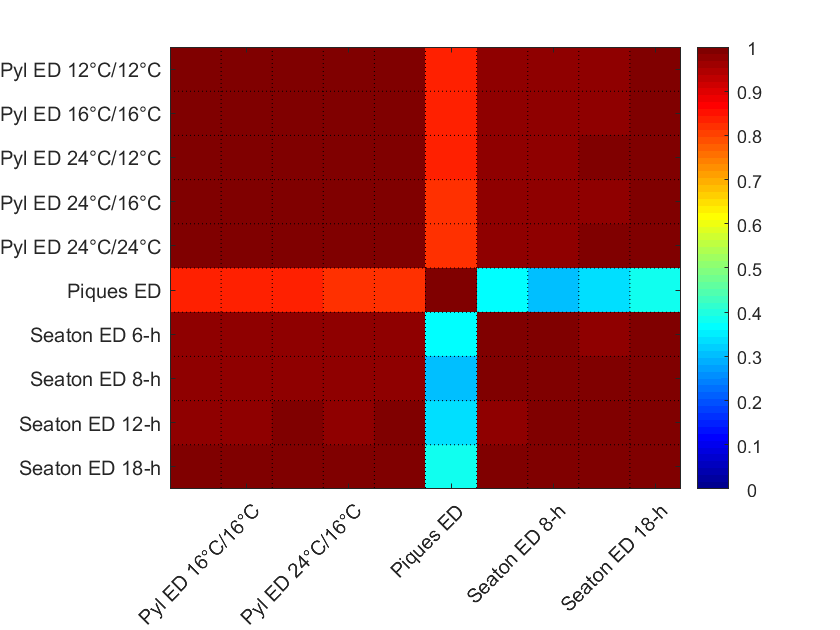

ans =   Image with properties:

           CData: [10×10×3 double]
    CDataMapping: 'direct'

  Show all properties


figure
label={'Pyl ED 12°C/12°C';'Pyl ED 16°C/16°C';'Pyl ED 24°C/12°C';'Pyl ED 24°C/16°C';'Pyl ED 24°C/24°C';'Piques ED';'Seaton ED 6-h';'Seaton ED 8-h';'Seaton ED 12-h';'Seaton ED 18-h'};
heatmap(corr(kapp_Vmax_combined_all,'rows','pairwise'),...
    label,label,[],'Colormap',jet,'ColorBar',0,'MinColorValue',0,'MaxColorValue',1,'NaNColor',[1 1 1],'GridLines', ':','TickAngle',45)


var_id = find(sum(kapp_Vmax_combined_all'>0));
kcat_estimated_vmax_combined = kapp_Vmax_combined_all(var_id,:);
vmax_combined = vmax_combined_all(var_id,:);
abundance_combined = abundance_per_EC_mg_gFW_combined_all(var_id,:);

disp('----------------------------------------------')

----------------------------------------------


disp('CV of estimated kapp_Vmax across conditions:')

CV of estimated kapp_Vmax across conditions:


CV=std(kapp_Vmax_combined_all(~all(isnan(kapp_Vmax_combined_all')),:)',0,1,"omitnan")./mean(kapp_Vmax_combined_all(~all(isnan(kapp_Vmax_combined_all')),:)','omitnan')

CV =     0.1356    0.7808    0.5261    0.4931    0.0503    0.4410    0.2717    0.1656    0.1268    0.1984    0.3584    0.9405    0.2276    0.6535    0.3390    0.4338    0.6073    0.2346    0.1025    0.1684    0.1639    0.0802    0.1373    0.5731    0.4360    0.4770    0.5350    0.0787    1.2211    0.1797    0.5065    0.1724    0.5257    0.5211    0.3002    0.4555    0.7189


disp('average CV of estimated kapp_Vmax across conditions:')

average CV of estimated kapp_Vmax across conditions:


mean(CV)

ans = 0.3875

## Supplementary Figure 1

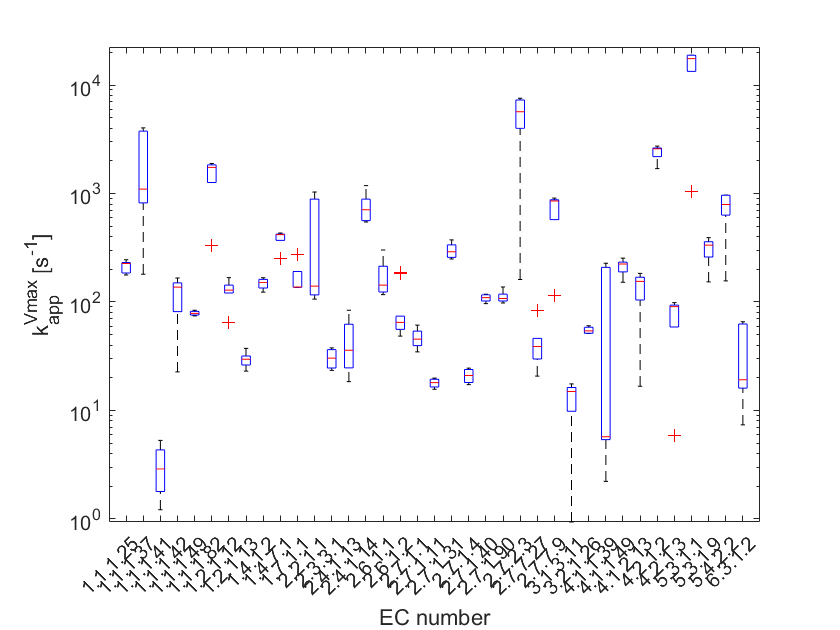

figure
boxplot(kapp_Vmax_combined_all(~all(isnan(kapp_Vmax_combined_all')),:)')
ylabel('k_{app}^{Vmax} [s^{-1}]')
xlabel('EC number')
xlim([0 length(var_id)+1])
set(gca,'XTick',1:length(var_id),'XTickLabel',EC(var_id),'XTickLabelRotation',45,'YScale','Log')

## Correlation $k_{\mathrm{app}}^{\mathrm{Vmax}}$ and $k_{\mathrm{cat}}$

disp('Number of enzymes:')

Number of enzymes:


length(intersect(find(~isnan(kcat_BRENDA_max)),find(~isnan(kapp_Vmax_combined_all_max))))

ans = 23


disp('Correlation kapp to mean kcat:')

Correlation kapp to mean kcat:


[C,P]=corr(log(kcat_BRENDA_mean),log(kapp_Vmax_combined_all_max),'rows','pairwise')

C = 0.4515

P = 0.0306


disp('Correlation kapp to median kcat:')

Correlation kapp to median kcat:


[C,P]=corr(log(kcat_BRENDA_median),log(kapp_Vmax_combined_all_max),'rows','pairwise')

C = 0.3096

P = 0.1505


disp('Correlation kapp to min kcat:')

Correlation kapp to min kcat:


[C,P]=corr(log(kcat_BRENDA_min(kcat_BRENDA_min>0)),log(kapp_Vmax_combined_all_max(kcat_BRENDA_min>0)),'rows','pairwise')

C = 0.0722

P = 0.7434


disp('Correlation kapp to max kcat:')

Correlation kapp to max kcat:


[C,P]=corr(log(kcat_BRENDA_max),log(kapp_Vmax_combined_all_max),'rows','pairwise')

C = 0.4818

P = 0.0199

## Figure 2

load('Names_of_example_enzymes.mat')

figure
subplot(2,2,4)
i=intersect(find(~isnan(kcat_BRENDA_mean)),find(~isnan(kapp_Vmax_combined_all_max)));

x = kcat_BRENDA_median(i);
y = kapp_Vmax_combined_all_max(i);
err_pos = kapp_Vmax_std_combined_all_max(i);
err_neg =  kapp_Vmax_std_combined_all_max(i);
err_neg(( kapp_Vmax_std_combined_all_max(i)- kapp_Vmax_std_combined_all_max(i))<0) =  kapp_Vmax_std_combined_all_max(( kapp_Vmax_std_combined_all_max(i)- kapp_Vmax_std_combined_all_max(i))<0);
errorbar(x,y,err_neg,err_pos,'vertical','.','MarkerSize',10)
text(kcat_BRENDA_median,kapp_Vmax_combined_all_max,NAMES,'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',8)
xlabel('median {\it in vitro} k_{cat} [s^{-1}]')
set(gca,'XScale','Log','YScale','Log')
xlim([1e0 1e5])
ylim([1e0 1e5])
hold on
plot([1e0 1e5],[1e0 1e5],'k')
hold on
[~,m,b]=regression(log(kcat_BRENDA_median)',log(kapp_Vmax_combined_all_max)');
x=log([1e0; 1e1; 1e2;1e3;1e4;1e5]);
y=(m.*x)+b;
plot(exp(x),exp(y),'-b')
fitlm(log(kcat_BRENDA_median)',log(kapp_Vmax_combined_all_max)')

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)     4.0108      1.0054    3.9892    0.00066668
    x1             0.31885     0.21366    1.4923       0.15049


Number of observations: 23, Error degrees of freedom: 21
Root Mean Squared Error: 1.9
R-squared: 0.0959,  Adjusted R-Squared: 0.0528
F-statistic vs. constant model: 2.23, p-value = 0.15


subplot(2,2,3)
i=intersect(find(~isnan(kcat_BRENDA_mean)),find(~isnan(kapp_Vmax_combined_all_max)));

x = kcat_BRENDA_mean(i);
y = kapp_Vmax_combined_all_max(i);
err_pos = kapp_Vmax_std_combined_all_max(i);
err_neg =  kapp_Vmax_std_combined_all_max(i);
err_neg(( kapp_Vmax_std_combined_all_max(i)- kapp_Vmax_std_combined_all_max(i))<0) =  kapp_Vmax_std_combined_all_max(( kapp_Vmax_std_combined_all_max(i)- kapp_Vmax_std_combined_all_max(i))<0);
errorbar(x,y,err_neg,err_pos,'vertical','.','MarkerSize',10)
text(kcat_BRENDA_mean,kapp_Vmax_combined_all_max,NAMES,'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',8)
ylabel('k_{cat}^{Vmax} [s^-1]')
xlabel('mean {\it in vitro} k_{cat} [s^{-1}]')
set(gca,'XScale','Log','YScale','Log')
xlim([1e0 1e5])
ylim([1e0 1e5])
hold on
plot([1e0 1e5],[1e0 1e5],'k')
hold on
[~,m,b]=regression(log(kcat_BRENDA_mean)',log(kapp_Vmax_combined_all_max)');
x=log([1e0; 1e1; 1e2;1e3;1e4;1e5]);
y=(m.*x)+b;
plot(exp(x),exp(y),'-b')
fitlm(log(kcat_BRENDA_mean)',log(kapp_Vmax_combined_all_max)')

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat      pValue  
                   ________    _______    ______    _________

    (Intercept)     3.4593     0.91172    3.7943    0.0010614
    x1               0.418     0.18027    2.3187     0.030576


Number of observations: 23, Error degrees of freedom: 21
Root Mean Squared Error: 1.78
R-squared: 0.204,  Adjusted R-Squared: 0.166
F-statistic vs. constant model: 5.38, p-value = 0.0306


subplot(2,2,1)
% plot(kcat_BRENDA_min,kapp_Vmax_combined_all_max,'.')
i=intersect(find(~isnan(kcat_BRENDA_min)),find(~isnan(kapp_Vmax_combined_all_max)));
x = kcat_BRENDA_min(i);
y = kapp_Vmax_combined_all_max(i);
err_pos = kapp_Vmax_std_combined_all_max(i);
err_neg = kapp_Vmax_std_combined_all_max(i);
err_neg((kapp_Vmax_combined_all_max(i)-kapp_Vmax_combined_all_max(i))<0) = kapp_Vmax_combined_all_max((kapp_Vmax_combined_all_max(i)-kapp_Vmax_combined_all_max(i))<0);
errorbar(x,y,err_neg,err_pos,'vertical','.','MarkerSize',10)
text(kcat_BRENDA_min,kapp_Vmax_combined_all_max,NAMES,'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',8)

xlabel('minimum in vitro k_{cat} [s^{-1}]')
ylabel('k_{cat}^{Vmax} [s^-1]')
set(gca,'XScale','Log','YScale','Log')
xlim([1e-4 1e5])
ylim([1e-4 1e5])
hold on
plot([1e-4 1e5],[1e-4 1e5],'k')
hold on
[~,m,b]=regression(log(kcat_BRENDA_min)',log(kapp_Vmax_combined_all_max)');
x=log([1e-4; 1e0; 1e1; 1e2;1e3;1e4;1e5]);
y=(m.*x)+b;
plot(exp(x),exp(y),'-b')
fitlm(log(kcat_BRENDA_min)',log(kapp_Vmax_combined_all_max)')

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)       5.338    0.44377     12.029    6.9664e-11
    x1             0.036564    0.11023    0.33171       0.74339


Number of observations: 23, Error degrees of freedom: 21
Root Mean Squared Error: 1.99
R-squared: 0.00521,  Adjusted R-Squared: -0.0422
F-statistic vs. constant model: 0.11, p-value = 0.743

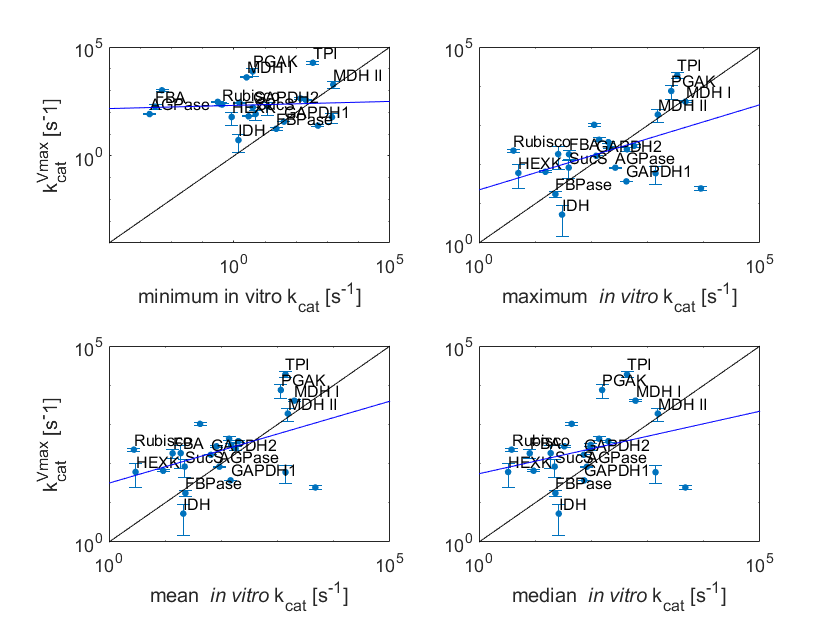


subplot(2,2,2)
% plot(kcat_BRENDA_max,kapp_Vmax_combined_all_max,'.')
i=intersect(find(~isnan(kcat_BRENDA_max)),find(~isnan(kapp_Vmax_combined_all_max)));
x = kcat_BRENDA_max(i);
y = kapp_Vmax_combined_all_max(i);
err_pos = kapp_Vmax_std_combined_all_max(i);
err_neg = kapp_Vmax_std_combined_all_max(i);
err_neg((kapp_Vmax_combined_all_max(i)-kapp_Vmax_combined_all_max(i))<0) = kapp_Vmax_combined_all_max((kapp_Vmax_combined_all_max(i)-kapp_Vmax_combined_all_max(i))<0);
errorbar(x,y,err_neg,err_pos,'vertical','.','MarkerSize',10)
text(kcat_BRENDA_max,kapp_Vmax_combined_all_max,NAMES,'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',8)

xlabel('maximum {\it in vitro} k_{cat} [s^{-1}]')
set(gca,'XScale','Log','YScale','Log')
% title('maximum {\it in vitro} k_{cat}')
xlim([1e0 1e5])
ylim([1e0 1e5])
hold on
plot([1e0 1e5],[1e0 1e5],'k')
hold on
[~,m,b]=regression(log(kcat_BRENDA_max)',log(kapp_Vmax_combined_all_max)');
x=log([1e0; 1e1; 1e2;1e3;1e4;1e5]);
y=(m.*x)+b;
plot(exp(x),exp(y),'-b')

fitlm(log(kcat_BRENDA_max)',log(kapp_Vmax_combined_all_max)')

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat      pValue 
                   ________    _______    ______    ________

    (Intercept)     3.1208     0.97176    3.2115     0.00419
    x1              0.4345     0.17246    2.5194    0.019925


Number of observations: 23, Error degrees of freedom: 21
Root Mean Squared Error: 1.75
R-squared: 0.232,  Adjusted R-Squared: 0.196
F-statistic vs. constant model: 6.35, p-value = 0.0199